% rgb
map=([1 1 0; 1 0 0; 0 1 1; 0.2 0.2 0.2; 1 0 1; 0.8 0.8 0.8])

map =     1.0000    1.0000         0
    1.0000         0         0
         0    1.0000    1.0000
    0.2000    0.2000    0.2000
    1.0000         0    1.0000
    0.8000    0.8000    0.8000


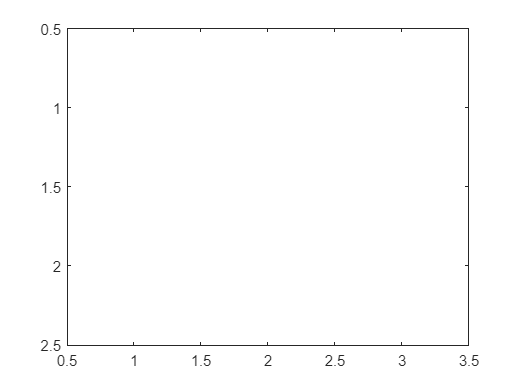

image([1 , 2 , 3; 4, 5, 6])
colormap(map)

N=[1 2 3; 4 5 6; 7 8 9; 10 11 12; 13 14 15]

N =      1     2     3
     4     5     6
     7     8     9
    10    11    12
    13    14    15


N(1:3:end, 1)

ans =      1
    10


N(1:3:end, :)

ans =      1     2     3
    10    11    12


v1=[1, 1, 1, 1]

v1 =      1     1     1     1


v2=[0.5, 0.25, 0, 0.25];
v3=[0.25, 0.5, 0, 0.5, 1]

v3 =     0.2500    0.5000         0    0.5000    1.0000


v1 .* v2

ans =     0.5000    0.2500         0    0.2500


s1=sum(v1 .* v2)

s1 = 1

%v1 .* v3
%s2=sum(v1 .* v3);

m6=[1 2 3; 4 5 6; 7 8 9];
m7=[-2 3 1; 0 2 -7; 1 3 6];

u1= m6>3

u1 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u2= (m6 > 3 & m7==-7)

u2 = 3×3 logical array
   0   0   0
   0   0   1
   0   0   0


u3= (m6 > 3 | m7==-7)

u3 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u4= ( (m6+m7) >= 4 & m6>5)

u4 = 3×3 logical array
   0   0   0
   0   0   0
   1   1   1


bild = imread('Butterfly.tif');
fargbild = double(bild) / 255;
mygray = (fargbild(:,:,1) + fargbild(:,:,2) + fargbild(:,:,3))/3;
imwrite(mygray, 'mygray.png');

mygrey = imread('mygray.png');
b61 = mygrey(1:2:end, 1:2:end);

b61 = 140×210 uint8 matrix
   46   46   61   58   54   50   51   50   50   59   64   69   68   64   64   62   55   65   60   62   53   55   54   56   54   53   49   47   49   47   47   48   42   43   44   45   45   43   45   43   42   40   44   45   42   44   39   46   39   45
   54   55   58   58   52   59   52   52   55   63   63   65   63   63   66   62   67   58   61   59   60   58   57   53   54   52   51   54   49   49   49   49   47   47   47   47   46   45   43   46   44   43   44   44   45   46   42   48   49   44
   57   67   63   53   53   60   48   51   57   58   60   65   65   63   64   64   61   60   60   57   61   57   59   51   56   50   49   50   47   50   52   48   47   46   45   43   47   48   44   43   44   45   44   44   46   45   43   46   47   46
   55   57   59   52   56   56   53   50   54   50   59   61   63   61   61   59   57   58   57   61   50   53   58   52   53   48   50   50   51   47   46   49   48   47   46   45   44   43   43   43   41   44   43   44

imwrite(b61, 'b61.png');

b63_nearest = imresize(b61, 2, 'nearest');

b63_nearest = 280×420 uint8 matrix
   46   46   46   46   61   61   58   58   54   54   50   50   51   51   50   50   50   50   59   59   64   64   69   69   68   68   64   64   64   64   62   62   55   55   65   65   60   60   62   62   53   53   55   55   54   54   56   56   54   54
   46   46   46   46   61   61   58   58   54   54   50   50   51   51   50   50   50   50   59   59   64   64   69   69   68   68   64   64   64   64   62   62   55   55   65   65   60   60   62   62   53   53   55   55   54   54   56   56   54   54
   54   54   55   55   58   58   58   58   52   52   59   59   52   52   52   52   55   55   63   63   63   63   65   65   63   63   63   63   66   66   62   62   67   67   58   58   61   61   59   59   60   60   58   58   57   57   53   53   54   54
   54   54   55   55   58   58   58   58   52   52   59   59   52   52   52   52   55   55   63   63   63   63   65   65   63   63   63   63   66   66   62   62   67   67   58   58   61   61   59   59   60   60  

b63_linear = imresize(b61, 2,'bilinear');

b63_linear = 280×420 uint8 matrix
   46   46   46   50   57   60   59   57   55   53   51   50   51   51   50   50   50   52   57   60   63   65   68   69   68   67   65   64   64   64   63   60   57   58   63   64   61   61   62   60   55   54   55   55   54   55   56   56   55   54
   48   48   48   51   57   60   59   57   55   54   53   52   51   51   51   51   51   53   58   61   63   65   67   68   67   66   65   64   65   64   63   61   59   59   62   62   61   60   61   60   57   55   56   56   55   55   55   55   54   54
   52   52   53   55   58   59   58   57   54   54   56   56   53   52   52   53   54   56   60   62   63   64   65   66   65   64   63   64   65   65   63   63   64   63   61   60   61   61   60   60   59   58   57   57   56   56   55   54   54   54
   55   56   57   58   59   59   58   56   53   54   57   57   53   51   52   53   55   58   61   62   62   63   64   65   64   64   63   64   65   65   64   64   65   64   61   60   61   61   60   59   60   60   

b63_cubic = imresize(b61, 2,'bicubic');

b63_cubic = 280×420 uint8 matrix
   45   45   44   48   58   62   59   57   55   53   50   49   51   51   50   50   49   52   57   61   63   65   68   69   69   67   65   64   64   64   63   60   55   56   64   66   61   60   62   60   54   52   54   55   54   54   56   56   55   54
   48   48   47   50   58   61   59   57   55   53   52   52   51   51   50   50   50   53   58   61   63   65   67   68   68   66   65   64   64   64   63   61   58   59   63   64   61   60   61   60   55   54   56   56   55   55   55   55   54   54
   52   52   52   53   57   59   59   57   53   53   56   56   53   52   52   52   53   56   61   64   63   64   66   66   65   64   63   64   66   65   63   62   65   64   60   59   61   61   60   60   59   59   57   57   56   56   54   54   54   54
   55   56   57   58   59   59   58   56   52   53   59   59   53   50   51   53   55   58   61   62   62   63   65   65   63   63   63   64   66   66   63   64   67   65   60   58   60   61   58   58   61   61   5


imwrite(b63_nearest, 'b63_nearest.png');
imwrite(b63_linear, 'b63_linear.png');
imwrite(b63_cubic, 'b63_cubic.png');